# Image Intensity and Color Distribution

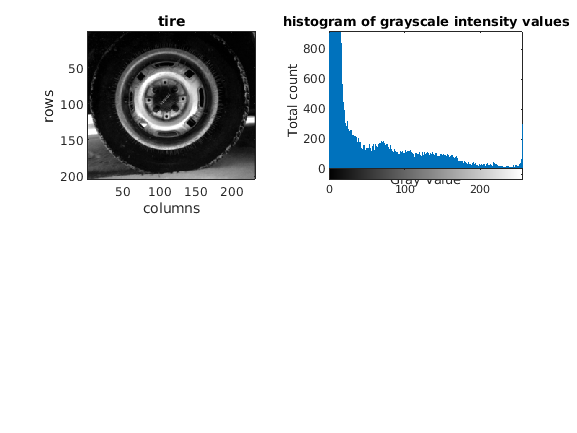

img= imread("tire.tif");
subplot(2,2,1);
imagesc(img);
colormap("gray");
title("tire");
xlabel("columns");
ylabel("rows");
axis equal;
axis tight;
subplot(2,2,2);
imhist(img);
title("histogram of grayscale intensity values");
xlabel("Gray Value");
ylabel("Total count");

## Improving Contrast Through Histogram Equalization

A basic image processing procedure we can perform to improve the contrast of such an image is called Histogram Equalization.

With this process we change intensity assignments of pixels in order to achieve a more uniform distribution of pixel counts across our intensity histogram.

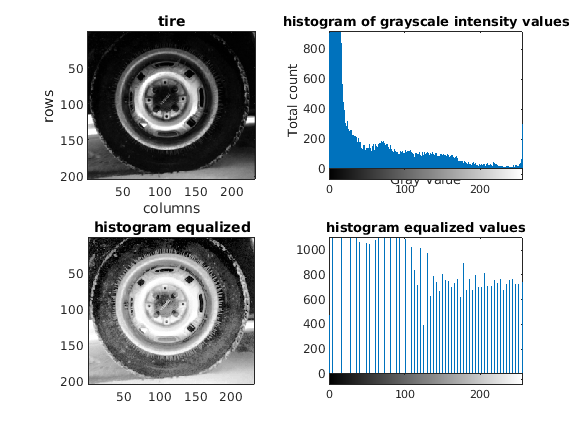

imgeq = histeq(img);
subplot(2,2,3);
imagesc(imgeq);
axis equal;
axis tight;
title("histogram equalized");
subplot(2,2,4);
imhist(imgeq);
title("histogram equalized values");

# Colored Images

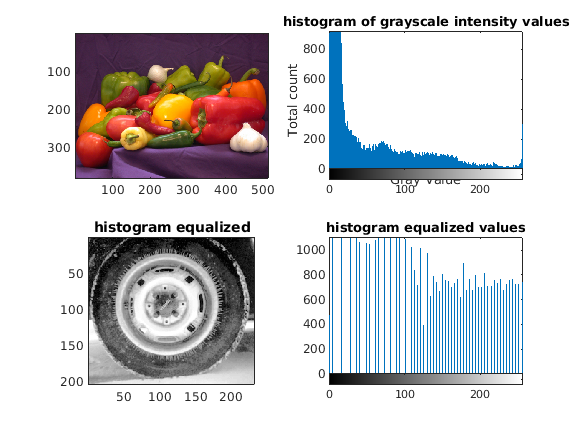

img = imread('peppers.png');
figure(2);
subplot(2,2,1);
imagesc(img);
axis tight;
axis equal;

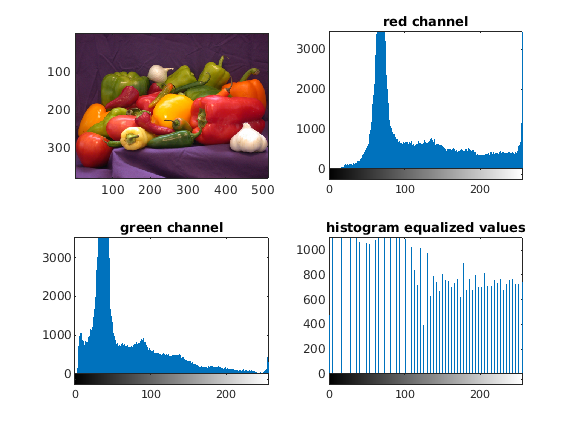

subplot(2,2,2);
imhist(img(:,:,1));
title("red channel");
subplot(2,2,3);
imhist(img(:,:,2));
title("green channel");

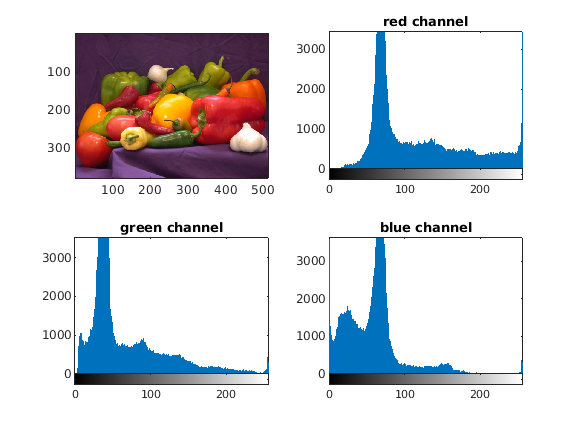

subplot(2,2,4);
imhist(img(:,:,3));
title("blue channel");

## Converting RGB to HSV

RGB image matrix to an equivalent HSV(Hue, Saturation,Value/Brightness) colorspace image matrix

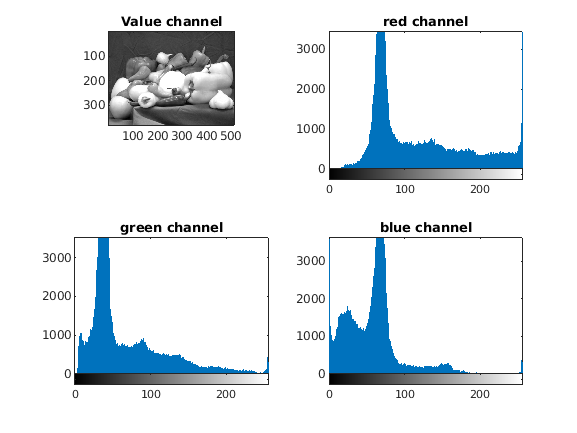

hsv = rgb2hsv(img);
figure(3);
subplot(3,2,1);
imagesc(hsv(:,:,3));
title("Value channel");
axis tight;
axis equal;

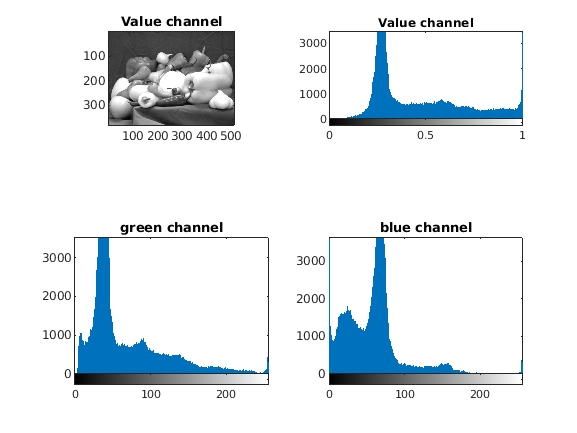

subplot(3,2,2);
imhist(hsv(:,:,3));
title("Value channel");

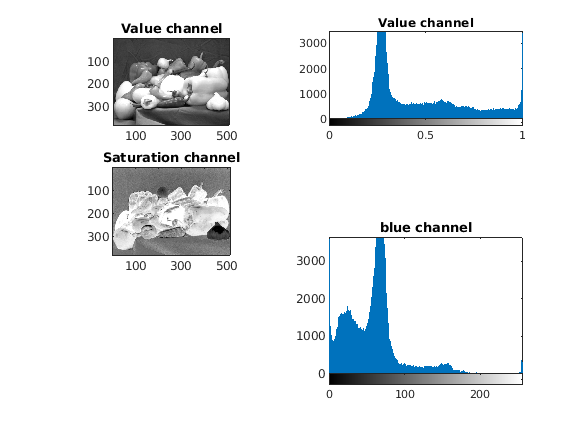

subplot(3,2,3);
imagesc(hsv(:,:,2));
title("Saturation channel");
axis tight;
axis equal;

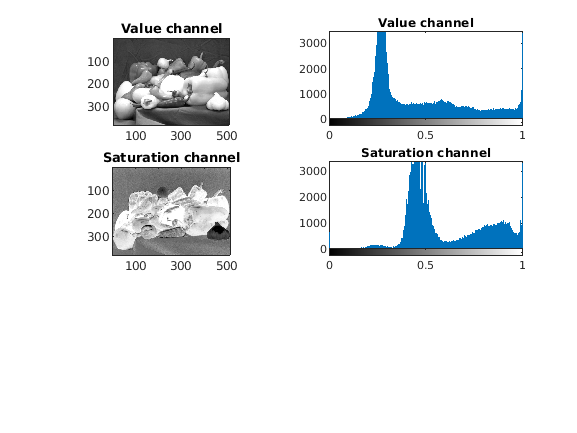

subplot(3,2,4);
imhist(hsv(:,:,2));
title("Saturation channel");

## Creating a colormap showing 256 different hues

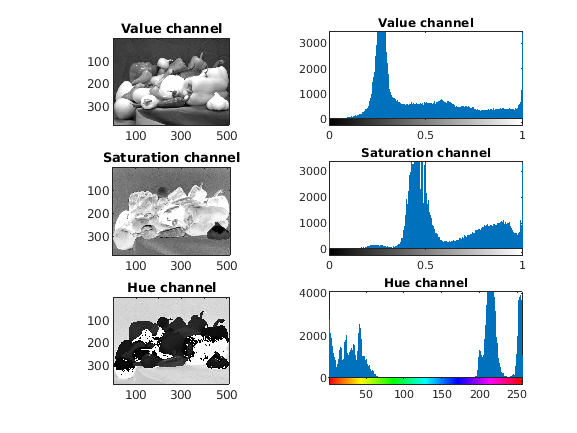

cmap = hsv2rgb([[0:1/255:1]',ones(256,2)]);
colormap(gca,cmap);

subplot(3,2,5);
imagesc(hsv(:,:,1));
title("Hue channel");
axis tight;
axis equal;
subplot(3,2,6);
imhist(round(hsv(:,:,1)*255)+1,cmap);
title("Hue channel");

## HSV Manipulations

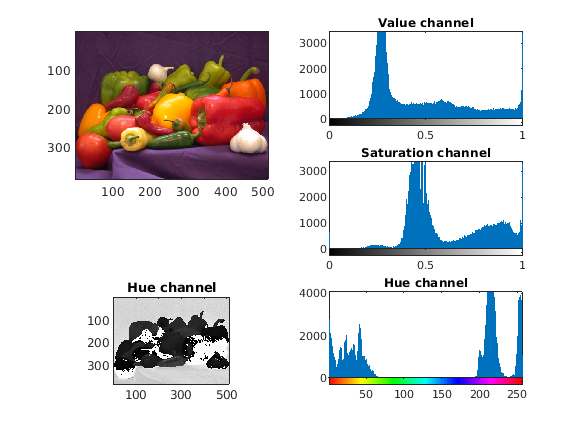

figure(4);
subplot(2,2,1);
imagesc(img);

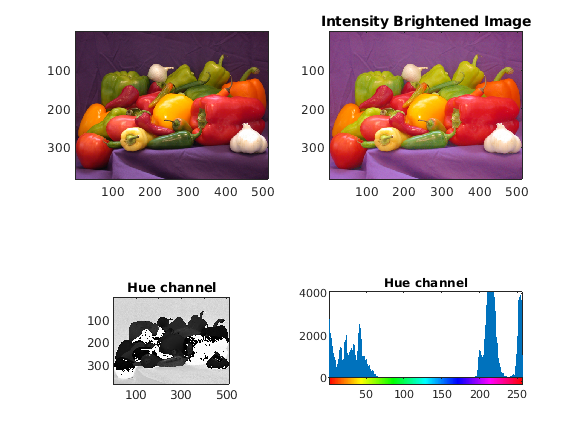

hsvbright = hsv;
hsvbright(:,:,3) = hsvbright(:,:,3).^.5;
subplot(2,2,2);
imagesc(hsv2rgb(hsvbright));
title("Intensity Brightened Image");

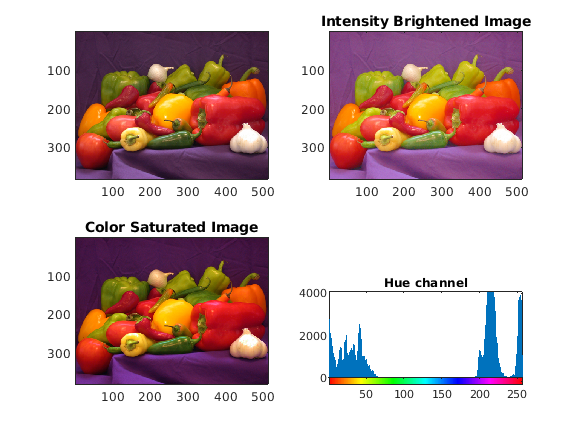

hsvsat = hsv;
hsvsat(:,:,2) = hsvsat(:,:,2).^.5;
subplot(2,2,3);
imagesc(hsv2rgb(hsvsat));
title("Color Saturated Image");

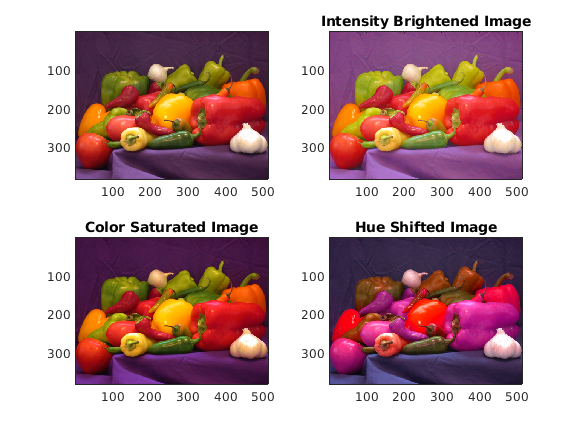

hsvhue = hsv;
hsvhue(:,:,1) = mod(hsvhue(:,:,1)-0.1,1);
subplot(2,2,4);
imagesc(hsv2rgb(hsvhue));
title("Hue Shifted Image");